# Cálculos Para Mecanismos de 4 y 5 Barras

Eduardo Santizo Olivet (16089)

### Mecanismo de 4 Barras

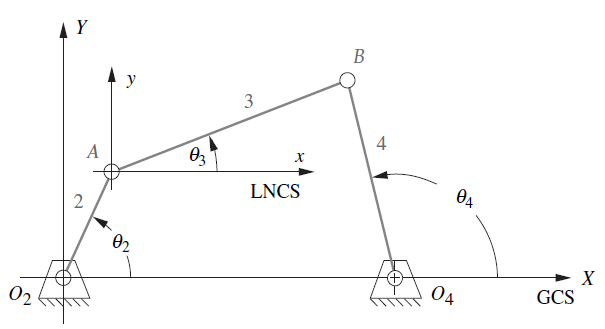

clear;

DeltaTiempo = 0.001;

% Velocidad Angular
w2 = 2;                     % rad/s

% Vector con todos los ángulos de 0 a 360
Theta2 = linspace(0,360,361);

% Transformación con respecto a las "Coordenadas Globales"
% Ángulos positivos = Ángulo por encima del eje X
% Ángulos negativos = Ángulo por debajo del eje Y
GlobalOffset = 85;

% Largo de cada eslabón
d = 9;      % Bancada
a = 7;      % Entrada
b = 11;     % Acoplador 
c = 6;      % Salida

% Largo de dimensiones de acoplador triangular 

l = 1;      % Parte de la base
r = 1;      % Alto

% Puntos a seguir

x = [-0.6 0.6 2.3 3 0.9 1.3 0.2 -0.1 -0.6];
y = [3 4 5 6 5.3 4.5 4.8 4.4 3.5];

% Condición de Grashof
Short = min([a b c d]);
Long = max([a b c d]);
PQ = sum([a b c d])-(Short+Long);

if (Short + Long) < PQ
    disp('Mecanismo Grashof');
elseif (Short + Long) == PQ
    disp('Mecanismo Especial Grashof');
else
    disp('Mecanismo No Grashof');
end

Mecanismo No Grashof


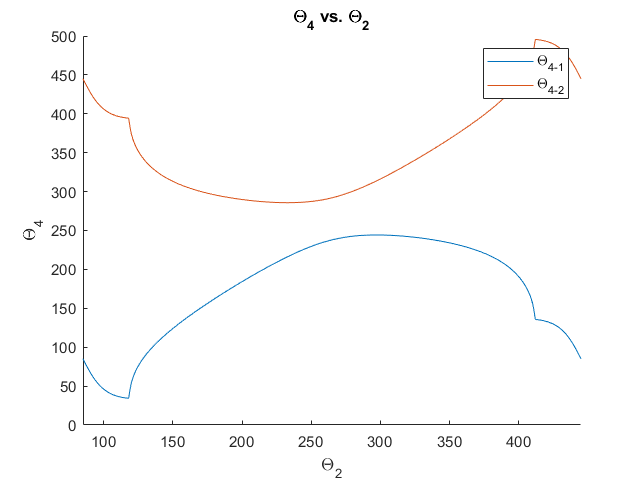


% Constantes K
K1 = d/a;
K2 = d/c;
K3 = (a^2 - b^2 + c^2 + d^2)/(2*a*c);
K4 = d/b;
K5 = (c^2 - d^2 - a^2 - b^2)/(2*a*b);

% Constantes A-F
A = cosd(Theta2) - K1 - (K2 .* cosd(Theta2)) + K3;
B = -2 * sind(Theta2);
C = K1 - ((K2+1) .* cosd(Theta2)) + K3;
D = cosd(Theta2) - K1 + (K4 .* cosd(Theta2)) + K5;
E = -2 .* sind(Theta2);
F = K1 + ((K4-1) .* cosd(Theta2)) + K5;


% Theta 4
Theta4(1,:) = real(2*atand((-B-sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset);
Theta4(2,:) = real(2*atand((-B+sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset);

Theta2 = Theta2 + GlobalOffset;

for i = 1:2
    if isempty(Theta4(Theta4(i,:) < 0)) == 0
        Theta4(i,:) = Theta4(i,:) + 360;
    end
end

figure(1); clf; hold on
plot(Theta2, Theta4(1,:));
plot(Theta2, Theta4(2,:));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])

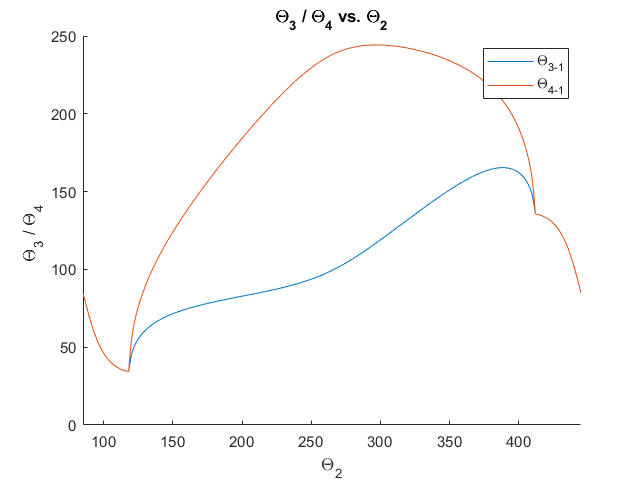

Theta2 = Theta2 - GlobalOffset;

% Theta 3
Theta3(1,:) = real(2*atand((-E-sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset);
Theta3(2,:) = real(2*atand((-E+sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset);

Theta2 = Theta2 + GlobalOffset;

for i = 1:2
    if isempty(Theta3(Theta3(i,:) < 0)) == 0
        Theta3(i,:) = Theta3(i,:) + 360;
    end
end

figure(2); clf; hold on
plot(Theta2, Theta3(1,:));
plot(Theta2, Theta4(1,:));
legend("\Theta_{3-1}", "\Theta_{4-1}")
title("\Theta_{3} / \Theta_4 vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3} / \Theta_4 ");
xlim([GlobalOffset 360+GlobalOffset])

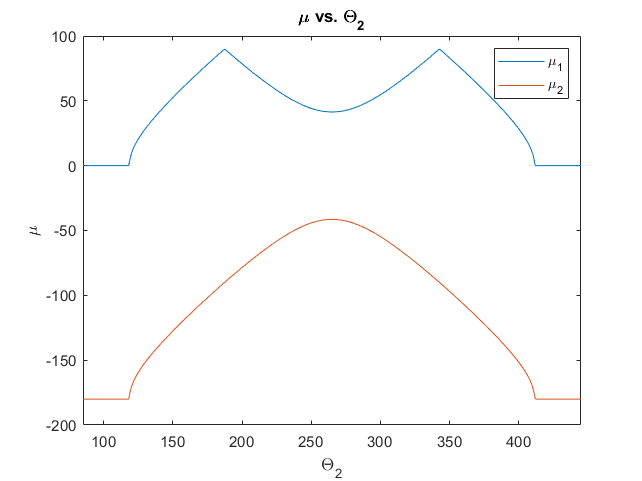

% Ángulo de Transmisión
Mu = abs(Theta3 - Theta4);
Mu(Mu > 90) = 180 - Mu(Mu > 90);

figure(3); clf;
plot(Theta2, Mu);
title("\mu vs. \Theta_2");
legend("\mu_1", "\mu_2")
xlabel("\Theta_2");
ylabel("\mu");
xlim([GlobalOffset 360+GlobalOffset])

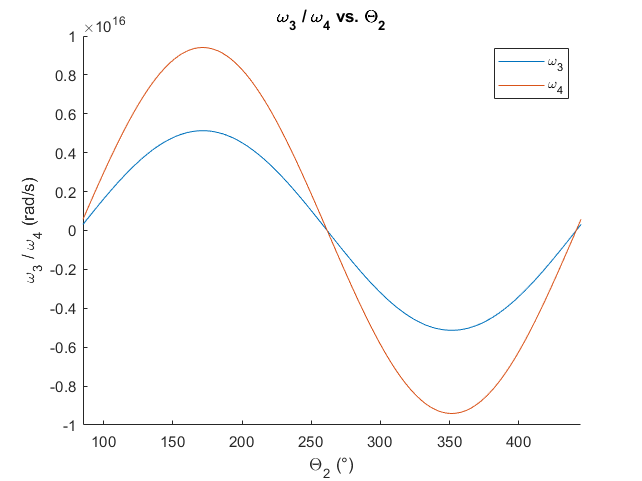

% Ángulo de agarrotamiento
%AAgarrotamiento = acosd()

%Mu_Min = min(Mu)

% Modo a visualizar
% Modo 1 = Normal
% Modo 2 = Inversión
Modo = 1;

% Velocidades Angulares
w3 = (a*w2/b) .* (sind(Theta4(Modo,i) - Theta2) ./ sind(Theta3(Modo,i) - Theta4(Modo,i)));
w4 = (a*w2/c) .* (sind(Theta2 - Theta3(Modo,i)) ./ sind(Theta4(Modo,i) - Theta3(Modo,i)));

figure(4); clf; hold on
plot(Theta2, w3);
plot(Theta2, w4);
legend("\omega_3", "\omega_4")
title("\omega_3 / \omega_4 vs. \Theta_2");
xlabel("\Theta_2 (°)");
ylabel("\omega_3 / \omega_4 (rad/s)");
xlim([GlobalOffset 360+GlobalOffset])

#### Animación del Mecanismo

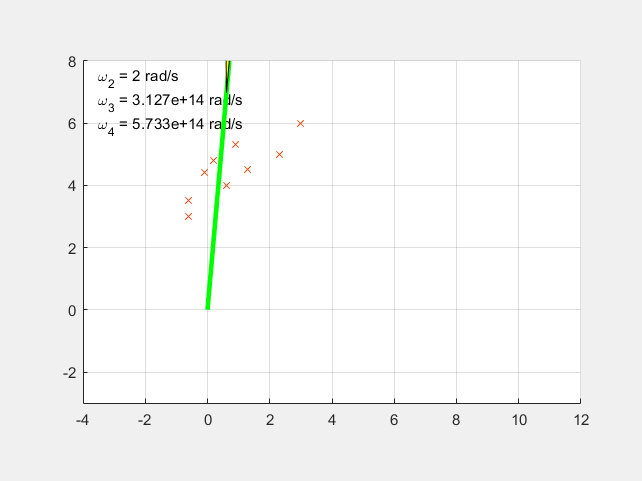

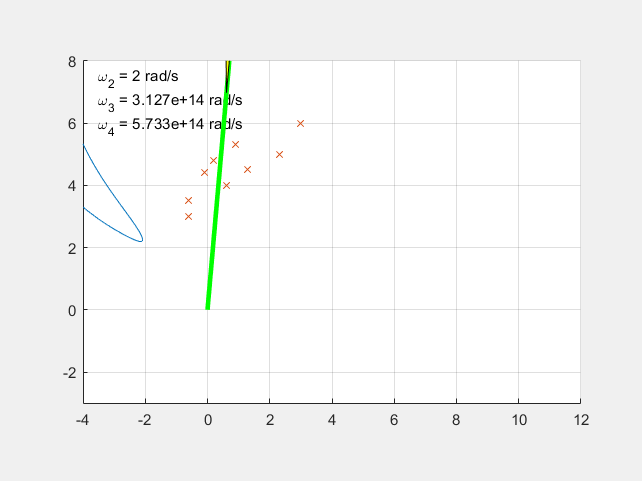

figure(5); clf;
figure('visible','on')

% Tipo de acoplador
% Acoplador 1 = Barra
% Acoplador 2 = Triangulo
Acoplador = 2;

% Guardar frames de animación en directorio seleccionado
% SaveFrames 1 = Si
% SaveFrames 0 = No
SaveFrames = 0;

hold on; axis equal; grid on;
XLimInf = -4;
XLimSup = 12;
YLimInf = -3;
YLimSup = 8;
axis([XLimInf XLimSup YLimInf YLimSup]);

TrayectoriaX = [];
TrayectoriaY = [];
j = 1;

% Posiciones para cada uno de los ángulos
PosXVelocidad = ((XLimSup - XLimInf)/100 * 3) + XLimInf;
PosYVelocidad = YLimSup - ((YLimSup - YLimInf)/100 * 5);
DeltaY = (YLimSup - YLimInf)/100 * 7;

% Animación
for i = 1:361
    cla; 
    
    % Velocidades Angulares
    text(PosXVelocidad,PosYVelocidad, strcat("\omega_2 = ", num2str(w2,4), " rad/s"));
    text(PosXVelocidad,PosYVelocidad - DeltaY, strcat("\omega_3 = ", num2str(w3(i),4), " rad/s"));
    text(PosXVelocidad,PosYVelocidad - 2*DeltaY, strcat("\omega_4 = ", num2str(w4(i),4), " rad/s"));
    
    % Eslabón A (Entrada)
    animatedline([0 a*cosd(Theta2(i))], [0 a*sind(Theta2(i))], 'Color','r','LineWidth',3);
    
    % Eslabón C (Salida)
    animatedline([d*cosd(GlobalOffset) d*cosd(GlobalOffset)+c*cosd(Theta4(Modo,i))], [d*sind(GlobalOffset) d*sind(GlobalOffset)+c*sind(Theta4(Modo,i))], 'Color', 'm', 'LineWidth',3);
    
    % Eslabón D (Bancada)
    animatedline([0 d*cosd(GlobalOffset)], [0 d*sind(GlobalOffset)], 'Color','g','LineWidth',3);
    
    % Eslabón B (Acoplador)
    if Acoplador == 1
        animatedline([a*cosd(Theta2(i)) a*cosd(Theta2(i))+b*cosd(Theta3(Modo,i))], [a*sind(Theta2(i)) a*sind(Theta2(i))+b*sind(Theta3(Modo,i))], 'Color', 'b', 'LineWidth',3);
    
    elseif Acoplador == 2
        % Coordenadas Vertices Triangulo
        PuntoA = [a*cosd(Theta2(i)) a*sind(Theta2(i))];
        PuntoB = [a*cosd(Theta2(i))+b*cosd(Theta3(Modo,i)) a*sind(Theta2(i))+b*sind(Theta3(Modo,i))];
        PuntaTriangulo = [PuntoB(1)-l*cosd(Theta3(Modo,i))+r*cosd(Theta3(Modo,i) + 90) PuntoB(2)-l*sind(Theta3(Modo,i))+r*sind(Theta3(Modo,i) + 90)];
        
        patch([PuntoA(1) PuntoB(1) PuntaTriangulo(1)],[PuntoA(2) PuntoB(2) PuntaTriangulo(2)], 'yellow');
        
        % Graficación de trayectoria generada
        TrayectoriaX = [TrayectoriaX PuntaTriangulo(1)];
        TrayectoriaY = [TrayectoriaY PuntaTriangulo(2)];
        plot(TrayectoriaX, TrayectoriaY);
        
        % Puntos utilizados como base
        scatter(x,y,'x');
    end
    
    % Guardado de Frames Numeradas
    if SaveFrames == 1
        if mod(i,2) == 0
            saveas(gcf, strcat('Pos',num2str(j),'.png'));
            j = j + 1;
        end
    end
    
    drawnow
end

### Mecanismo Manivela Corredera

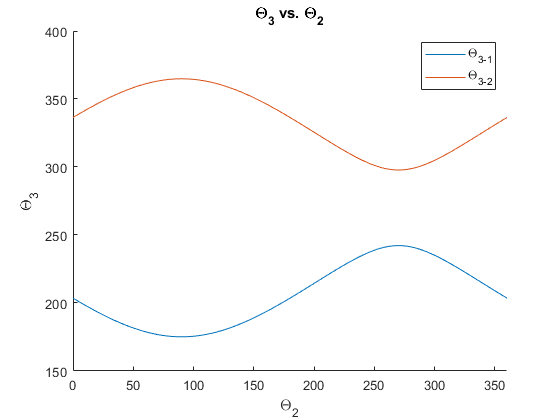

% Vector con todos los ángulos de 0 a 360
clear;
Theta2 = linspace(0,360,361);

% Transformación con respecto a las "Coordenadas Globales"
% Ángulos positivos = Ángulo por encima del eje X
% Ángulos negativos = Ángulo por debajo del eje Y
GlobalOffset = 0;

% Largo de cada eslabón
a = 63;
b = 130;
c = 52;

% Theta 3
Theta3(2,:) = asind((a*sind(Theta2) - c) / b) + GlobalOffset;
Theta3(1,:) = asind(-(a*sind(Theta2) - c) / b) + 180 + GlobalOffset;

for i = 1:2
    if isempty(Theta3(Theta3(i,:) < 0)) == 0
        Theta3(i,:) = Theta3(i,:) + 360;
    end
end

Theta2 = Theta2 + GlobalOffset;

figure(6); clf; hold on
plot(Theta2, Theta3(1,:));
plot(Theta2, Theta3(2,:));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

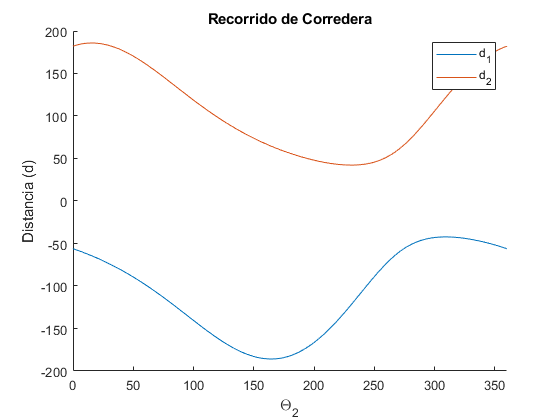


% Distancia Horizontal Corredera (d)
d(2,:) = a*cosd(Theta2-GlobalOffset) - b*cosd(Theta3(1,:)-GlobalOffset);
d(1,:) = a*cosd(Theta2-GlobalOffset) - b*cosd(Theta3(2,:)-GlobalOffset);

figure(7); clf; hold on
plot(Theta2, d(1,:));
plot(Theta2, d(2,:));
legend("d_1", "d_2")
title("Recorrido de Corredera");
xlabel("\Theta_2");
ylabel("Distancia (d)");
xlim([GlobalOffset 360+GlobalOffset])


% Cálculo de Carrera
Carrera(1) = max(d(1,:)) - min(d(1,:));
Carrera(2) = max(d(2,:)) - min(d(2,:));

% Compensamiento de Theta 3 para obtener ángulos 
% utilizables en la animación posterior
Theta3 = Theta3 - 180;

#### Animación del Mecanismo

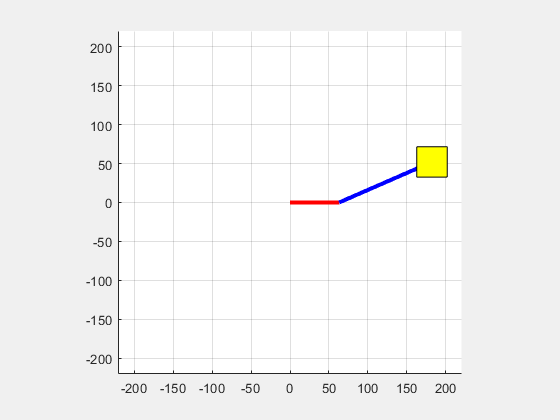

figure(8); clf;
figure('visible','on')

% Modo a animar
% Modo 1 = Normal
% Modo 2 = Cruzado
Modo = 1;

hold on; axis equal; grid on;

% Establecimiento de Límites
Margen = 1.5;
axis([-220 220 -220 220]);

PosFinalA(1,:) = a*cosd(Theta2);
PosFinalA(2,:) = a*sind(Theta2);

% Animación
for i = 1:361
    cla; 
    
    % Eslabón A
    animatedline([0 PosFinalA(1,i)], [0 PosFinalA(2,i)], 'Color','r','LineWidth',3);
    
    % Eslabón B
    animatedline([PosFinalA(1,i) PosFinalA(1,i)+b*cosd(Theta3(Modo,i))], [PosFinalA(2,i) PosFinalA(2,i)+b*sind(Theta3(Modo,i))], 'Color', 'b', 'LineWidth',3);
    
    % Pistón
    CentroPistonXInf = a*cosd(Theta2(i)) + b*cosd(Theta3(Modo,i)) - (b*0.3/2)*cosd(GlobalOffset);
    CentroPistonXSup = a*cosd(Theta2(i)) + b*cosd(Theta3(Modo,i)) + (b*0.3/2)*cosd(GlobalOffset);
    CentroPistonYInf = a*sind(Theta2(i)) + b*sind(Theta3(Modo,i)) - (b*0.3/2)*sind(GlobalOffset);
    CentroPistonYSup = a*sind(Theta2(i)) + b*sind(Theta3(Modo,i)) + (b*0.3/2)*sind(GlobalOffset);
    AjusteX = (b*0.3/2)*cosd(90 - GlobalOffset);
    AjusteY = (b*0.3/2)*sind(90 - GlobalOffset);
    
    patch([CentroPistonXInf+AjusteX CentroPistonXInf-AjusteX CentroPistonXSup-AjusteX CentroPistonXSup+AjusteX],[CentroPistonYInf-AjusteY CentroPistonYInf+AjusteY CentroPistonYSup+AjusteY CentroPistonYSup-AjusteY], 'yellow');
    
    drawnow
    
end

### Mecanismo de 5 Barras

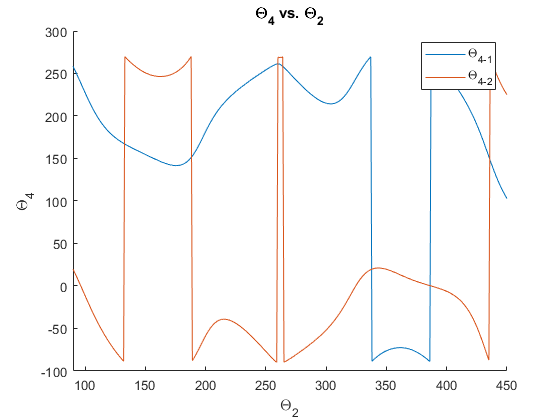


% Offset Global
clear;
GlobalOffset = 90;

% Longitudes de eslabón
a = 5;
b = 7;
c = 8;
d = 4; 
f = 6;
Lambda = -2.5;
Phi = 60;

% Vector con todos los ángulos de 0 a 360
Theta2 = linspace(0,360,361);
Theta5 = Theta2*Lambda + Phi;

% Theta 4
A = 2*c*(d*cosd(Lambda*Theta2 + Phi) - a*cosd(Theta2) + f);
B = 2*c*(d*sind(Lambda*Theta2 + Phi) - a*sind(Theta2));
C = a^2 - b^2 + c^2 + d^2 + f^2 - 2*a*f*cosd(Theta2) ...
    -2*d*(a*cosd(Theta2) - f).*cosd(Lambda*Theta2 + Phi) ...
    -2*a*d*sind(Theta2).*sind(Lambda*Theta2 + Phi);

D = C - A;
E = 2*B;
F = A + C;

Theta4(1,:) = 2*atand((-E - sqrt(E.^2 - 4*D.*F))./(2*D)) + GlobalOffset;
Theta4(2,:) = 2*atand((-E + sqrt(E.^2 - 4*D.*F))./(2*D)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;

figure(9); clf; hold on
plot(Theta2, real(Theta4(1,:)));
plot(Theta2, real(Theta4(2,:)));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])

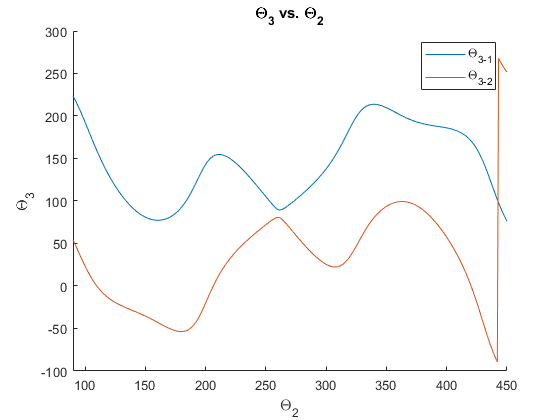


Theta2 = Theta2 - GlobalOffset;

% Theta 3
G = 2*b*(a*cosd(Theta2) - d*cosd(Lambda*Theta2 + Phi) - f);
H = 2*b*(a*sind(Theta2) - d*sind(Lambda*Theta2 + Phi));
K = a^2 + b^2 - c^2 + d^2 + f^2 - 2*a*f*cosd(Theta2) ...
    -2*d*(a*cosd(Theta2) - f).*cosd(Lambda*Theta2 + Phi) ...
    -2*a*d*sind(Theta2).*sind(Lambda*Theta2 + Phi);

L = K - G;
M = 2*H;
N = G + K;

Theta3(1,:) = 2*atand((-M+sqrt(M.^2-4*L.*N))./(2*L)) + GlobalOffset;
Theta3(2,:) = 2*atand((-M-sqrt(M.^2-4*L.*N))./(2*L)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;
Theta5 = Theta5 + GlobalOffset;

figure(10); clf; hold on
plot(Theta2, real(Theta3(1,:)));
plot(Theta2, real(Theta3(2,:)));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

#### Animación del Mecanismo

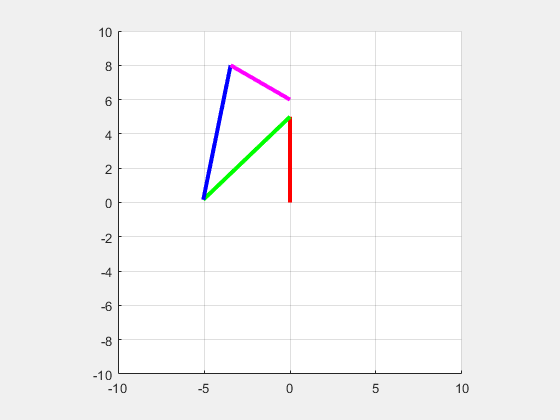

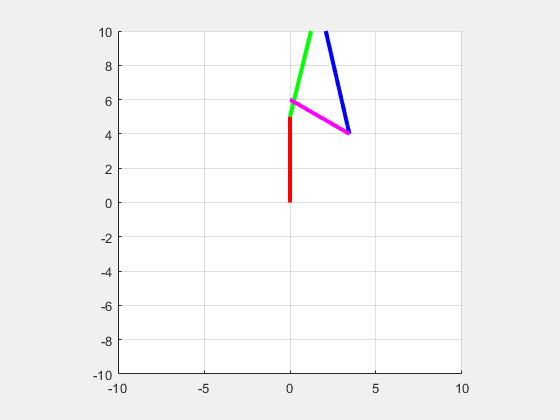

figure(11); clf;
figure('visible','on')

% Modo a animar
% Modo 1 = Normal
% Modo 2 = Cruzado
Modo = 1;

hold on; axis equal; grid on;

% Establecimiento de Límites
axis([-10 10 -10 10]);

% Animación
for i = 1:361
    cla; 
    
    % Eslabón A
    animatedline([0 a*cosd(Theta2(i));], [0 a*sind(Theta2(i));], 'Color','r','LineWidth',3);
    
    % Eslabón B
    animatedline([a*cosd(Theta2(i)) a*cosd(Theta2(i))+b*cosd(real(Theta3(Modo,i)))], [a*sind(Theta2(i)) a*sind(Theta2(i))+b*sind(real(Theta3(Modo,i)))], 'Color', 'g', 'LineWidth',3);
    
    % Eslabón C
    animatedline([f*cosd(GlobalOffset)+d*cosd(Theta5(i)) f*cosd(GlobalOffset)+d*cosd(Theta5(i))+c*cosd(real(Theta4(Modo,i)))], [f*sind(GlobalOffset)+d*sind(Theta5(i)) f*sind(GlobalOffset)+d*sind(Theta5(i))+c*sind(real(Theta4(Modo,i)))], 'Color', 'b', 'LineWidth',3);
    
    % Eslabón D
    animatedline([f*cosd(GlobalOffset) f*cosd(GlobalOffset)+d*cosd(Theta5(i))], [f*sind(GlobalOffset) f*sind(GlobalOffset)+d*sind(Theta5(i))], 'Color', 'm', 'LineWidth',3);
    
    drawnow
end

### Manivela Corredera Inversión 3

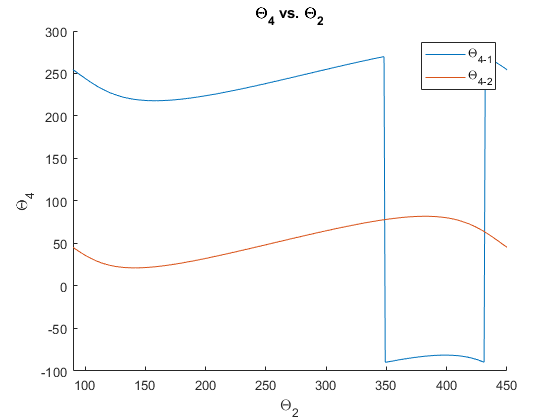


% Offset Global
clear;
GlobalOffset = 90;

% Longitudes de eslabón
a = 4;
c = 2;
d = 8; 
Gamma = 30;

% Theta 2
Theta2 = linspace(0,360,361);

% Theta 4

P = a*sind(Theta2)*sind(Gamma) + (a*cosd(Theta2) - d)*cosd(Gamma);
Q = -a*sind(Theta2)*cosd(Gamma) + (a*cosd(Theta2) - d)*sind(Gamma);
R = -c*sind(Gamma);

S = R - Q;
T = 2*P;
U = Q + R;

Theta4(1, :) = real(2*atand((-T + sqrt(T.^2 - 4*S.*U))./(2*S)));
Theta4(2, :) = real(2*atand((-T - sqrt(T.^2 - 4*S.*U))./(2*S)));

% Theta 3

Theta3(1, :) = Theta4(1, :) + Gamma;
Theta3(2, :) = Theta4(2, :) + Gamma;

% Distancia B

b(1,:) = (a*sind(Theta2) - c*sind(Theta4(1,:)))./sind(Theta3(1,:));
b(2,:) = (a*sind(Theta2) - c*sind(Theta4(2,:)))./sind(Theta3(2,:));

% Ajuste de Global Offset

Theta4 = Theta4 + GlobalOffset;
Theta3 = Theta3 + GlobalOffset;
Theta2 = Theta2 + GlobalOffset;

figure(12); clf; hold on
plot(Theta2, Theta4(1,:));
plot(Theta2, Theta4(2,:));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])

#### Animación del Mecanismo

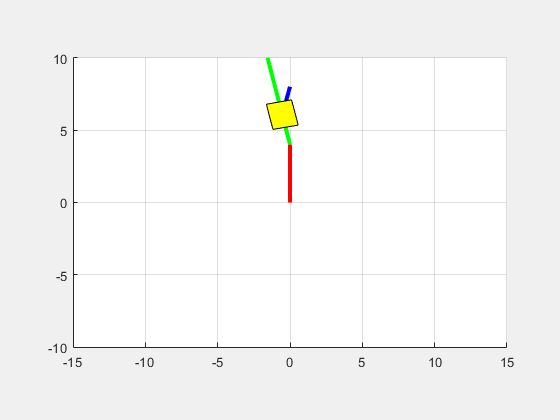

figure(13); clf;
figure('visible','on')

% Modo a animar
% Modo 1 = Normal
% Modo 2 = Cruzado
Modo = 1;

hold on; axis equal; grid on;

% Establecimiento de Límites
axis([-15 15 -10 10]);

% Animación
for i = 1:361
    cla; 
    
    % Eslabón A
    animatedline([0 a*cosd(Theta2(i));], [0 a*sind(Theta2(i));], 'Color','r','LineWidth',3);
    
    % Eslabón B
    animatedline([a*cosd(Theta2(i)) a*cosd(Theta2(i))+(a+c+d)*sign(b(Modo,i))*cosd(Theta3(Modo,i) - 180)], [a*sind(Theta2(i)) a*sind(Theta2(i))+(a+c+d)*sign(b(Modo,i))*sind(Theta3(Modo,i) - 180)], 'Color', 'g', 'LineWidth',3);
    
    % Eslabón C
    animatedline([d*cosd(GlobalOffset) d*cosd(GlobalOffset)+c*cosd(Theta4(Modo,i))], [d*sind(GlobalOffset) d*sind(GlobalOffset)+c*sind(Theta4(Modo,i))], 'Color', 'b', 'LineWidth',3);
    
    % Corredera
    CentroPistonXInf = a*cosd(Theta2(i)) + b(Modo,i)*cosd(Theta3(Modo,i) - 180) - ((a+c)*0.3/2)*cosd(Theta3(Modo,i) - 180);
    CentroPistonXSup = a*cosd(Theta2(i)) + b(Modo,i)*cosd(Theta3(Modo,i) - 180) + ((a+c)*0.3/2)*cosd(Theta3(Modo,i) - 180);
    CentroPistonYInf = a*sind(Theta2(i)) + b(Modo,i)*sind(Theta3(Modo,i) - 180) - ((a+c)*0.3/2)*sind(Theta3(Modo,i) - 180);
    CentroPistonYSup = a*sind(Theta2(i)) + b(Modo,i)*sind(Theta3(Modo,i) - 180) + ((a+c)*0.3/2)*sind(Theta3(Modo,i) - 180);
    AjusteX = ((a+c)*0.3/2)*cosd(90 - Theta3(Modo,i) - 180);
    AjusteY = ((a+c)*0.2/2)*sind(90 - Theta3(Modo,i) - 180);
    
    patch([CentroPistonXInf+AjusteX CentroPistonXInf-AjusteX CentroPistonXSup-AjusteX CentroPistonXSup+AjusteX],[CentroPistonYInf-AjusteY CentroPistonYInf+AjusteY CentroPistonYSup+AjusteY CentroPistonYSup-AjusteY], 'yellow');
    
    drawnow
end

### Mecanismo de 6 Barras de Watt

% Vector con todos los ángulos de 0 a 360
clear;
Theta2 = linspace(0,360,361);

% Transformación con respecto a las "Coordenadas Globales"
% Ángulos positivos = Ángulo por encima del eje X
% Ángulos negativos = Ángulo por debajo del eje Y
GlobalOffset = 0;

% Largo de cada eslabón
d = 150;
a = 30;
b = 150;
c = 30;

% Constantes K
K1 = d/a;
K2 = d/c;
K3 = (a^2 - b^2 + c^2 + d^2)/(2*a*c);
K4 = d/b;
K5 = (c^2 - d^2 - a^2 - b^2)/(2*a*b);

% Constantes A-F
A = cosd(Theta2) - K1 - (K2 .* cosd(Theta2)) + K3;
B = -2 * sind(Theta2);
C = K1 - ((K2+1) .* cosd(Theta2)) + K3;
D = cosd(Theta2) - K1 + (K4 .* cosd(Theta2)) + K5;
E = -2 .* sind(Theta2);
F = K1 + ((K4-1) .* cosd(Theta2)) + K5;

% Theta 4
Theta4(1,:) = 2*atand((-B-sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset;
Theta4(2,:) = 2*atand((-B+sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;

for i = 1:2
    if isempty(Theta4(Theta4(i,:) < 0)) == 0
        Theta4(i,:) = Theta4(i,:) + 360;
    end
end

figure(1); clf; hold on
plot(Theta2, Theta4(1,:));
plot(Theta2, Theta4(2,:));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])
Theta2 = Theta2 - GlobalOffset;

% Theta 3
Theta3(1,:) = 2*atand((-E-sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset;
Theta3(2,:) = 2*atand((-E+sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;

for i = 1:2
    if isempty(Theta3(Theta3(i,:) < 0)) == 0
        Theta3(i,:) = Theta3(i,:) + 360;
    end
end

figure(2); clf; hold on
plot(Theta2, Theta3(1,:));
plot(Theta2, Theta3(2,:));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

% Ángulo de Transmisión
Mu = abs(Theta3 - Theta4);
Mu(Mu > 90) = 180 - Mu(Mu > 90);

figure(3); clf;
plot(Theta2, Mu);
title("\mu vs. \Theta_2");
legend("\mu_1", "\mu_2")
xlabel("\Theta_2");
ylabel("\mu");
xlim([GlobalOffset 360+GlobalOffset])